% 优化 SVM 回归
% 此示例展示了如何使用 fitrsvm 自动优化超参数。 
% 该示例使用 carsmall 数据。
% 加载 carsmall 数据集。
% Optimize SVM Regression
% This example shows how to optimize hyperparameters automatically using fitrsvm. 
% The example uses the carsmall data.
% Load the carsmall data set.
clear
load carsmall

## 指定马力和重量作为预测变量 (X)，指定 MPG 作为响应变量 (Y)。

Specify Horsepower and Weight as the predictor variables (X) and MPG as the response variable (Y).

X = [Horsepower Weight];
Y = MPG;

## 通过使用自动超参数优化，找到将五倍交叉验证损失最小化的超参数。

为了重现性，设置随机种子并使用“预期改进加”采集功能。 Find hyperparameters that minimize five-fold cross-validation loss by using automatic hyperparameter optimization. For reproducibility, set the random seed and use the 'expected-improvement-plus' acquisition function.

|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |      4.1981 |     0.31273 |      4.1981 |      4.1981 |    0.0084663 |       510.98 |     0.016185 |         true |
|    2 | Best   |      2.9429 |     0.20164 |      2.9429 |      3.0186 |       45.353 |      0.47041 |     0.020424 |         true |
|    3 | Accept |      4.1889 |    0.076329 |      2.9429 |       2.943 |    0.0012899 |     0.057544 |       42.794 |         true |
|    4 | Accept |      4.1889 |    0.057331 |      2.9429 |   

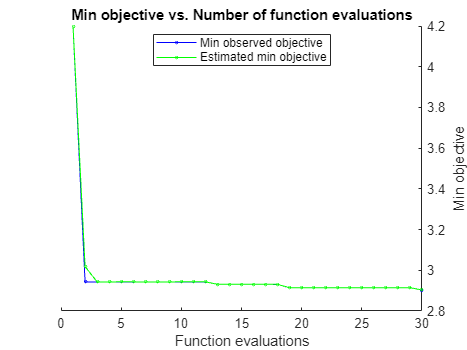

Mdl =   RegressionSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                                Alpha: [92×1 double]
                                 Bias: 46.4880
                     KernelParameters: [1×1 struct]
                      NumObservations: 94
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                       BoxConstraints: [94×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [94×1 logical]
                               Solver: 'SMO'


  Properties, Methods


rng default
Mdl = fitrsvm(X,Y,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))


% 优化搜索了 BoxConstraint、KernelScale 和 Epsilon。 
% 输出是具有最小估计交叉验证损失的回归。
% The optimization searched over BoxConstraint, KernelScale, and Epsilon. 
% The output is the regression with the minimum estimated cross-validation loss.